## 1D field visualization

TODO

- add GAUSS, LINEAR

- interp not working

- lower the grid resolution

generate map

grid = OctoGrid(2,2,2,10);

% add wall
grid.addBox(0.7,0.8,0,0.8,0.1,1.5);

generate phase

y = 0.001:0.001:1.999;

sample map

map_list = [];

x = 1;
z = 1;

% list of obstacle values
map_list = [map_list grid.grid(ceil(y*grid.resolution), x*grid.resolution, z*grid.resolution)];

generate kernels

rep_kernels = REP_kernels('type', 'linear', 'sigma', 2, 'kernel_length', 10, 'kernel_width', 4, 'kernel_height', 4);

generate LINEAR, GAUSS, LINEAR+INTERP, GAUSS+INTERP samples

rep_values = [];
tic()
for i = y
    rep_values = [rep_values REP_field_calculation(grid, rep_kernels, [x,i,z], 'interpolation_mode', false)'];
end
toc()

Elapsed time is 0.413997 seconds.


plot samples

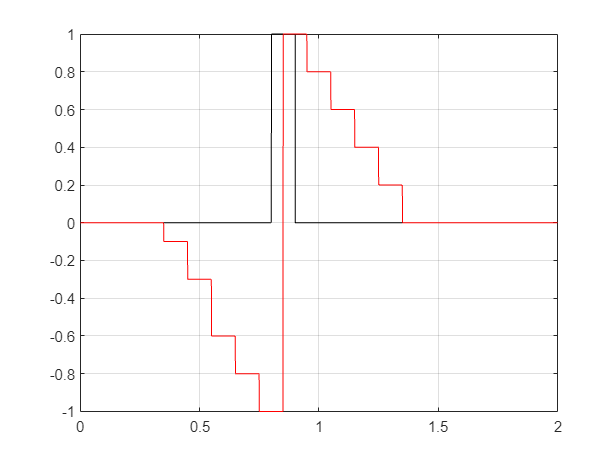

figure()
plot(y, map_list,'black')
hold on
plot(y, (rep_values(2,:))/max(rep_values(2,:)),'red')
grid on

% hold on

add legend

## 2D / 3D field visualization

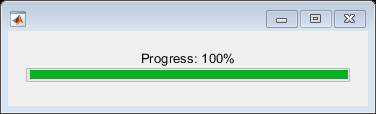

x = 0.1:0.01:2;
y = 0.1:0.01:2;

rep_values_2Dx = [];
rep_values_2Dy = [];

rep_values_2Dx_i = [];
rep_values_2Dy_i = [];

map_matrix = [];

% Initialize waitbar
h = waitbar(0, 'Progress: 0%');

for j = x
    rep_values_1D = [];
    rep_values_1D_i = [];

    map_matrix_1D = [];

    for i = y
%         tic()
        rep_values_1D = [rep_values_1D REP_field_calculation(grid, rep_kernels, [j,i,z],'interpolation_mode', false)'];
        rep_values_1D_i = [rep_values_1D_i REP_field_calculation(grid, rep_kernels, [j,i,z],'interpolation_mode', true)'];

        map_matrix_1D = [map_matrix_1D grid.grid(round(i*grid.resolution), round(j*grid.resolution), 0.5*grid.resolution)];

%         toc()
    end
    rep_values_2Dx = [rep_values_2Dx ; rep_values_1D(1,:)];
    rep_values_2Dy = [rep_values_2Dy ; rep_values_1D(2,:)];

    rep_values_2Dx_i = [rep_values_2Dx_i ; rep_values_1D_i(1,:)];
    rep_values_2Dy_i = [rep_values_2Dy_i ; rep_values_1D_i(2,:)];

    map_matrix = [map_matrix ; map_matrix_1D];

    % Update progress bar
    waitbar(j / x(end), h, sprintf('Progress: %d%%', round(j / x(end) * 100)));
end

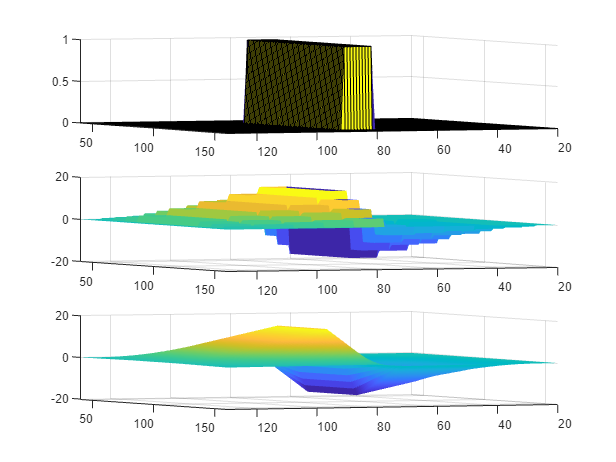

figure()
subplot(3,1,1)
surf(map_matrix)
xlim([20 130]);   % X-axis limits
ylim([40 160]);   % Y-axis limits
view([156.1 7.6])
subplot(3,1,2)
surf(((rep_values_2Dy )), 'EdgeColor', 'none')
xlim([20 130]);   % X-axis limits
ylim([40 160]);   % Y-axis limits
view([156.1 7.6])
subplot(3,1,3)
surf(((rep_values_2Dy_i )), 'EdgeColor', 'none')
xlim([20 130]);   % X-axis limits
ylim([40 160]);   % Y-axis limits
view([156.1 7.6])